%clearvars -except glodb

slim_pickings = find(strcmp(glodb.AP_quality, 'good') & ...
    (glodb.GLO_gloexp_pres1_40_500ms_wsr < 0.05 | ...
    glodb.GLO_gloexp_global_oddball_40_500ms_wsr < 0.05 | ...
    glodb.GLO_gloexp_local_oddball_40_500ms_wsr < 0.05) & ...
    glodb.GLO_rndctl_pres1_40_500ms_wsr < 0.05 & ...
    glodb.GLO_seqctl_pres1_40_500ms_wsr < 0.05 & ...
    abs(glodb.GLO_gloexp_pres1_40_500ms_mean) > 2 & ...
    abs(glodb.GLO_rndctl_pres1_40_500ms_mean) > 2 & ...
    abs(glodb.GLO_seqctl_pres1_40_500ms_mean) > 2);

%OWN SLIMMINING
slim_pickings = slim_pickings(opto_activated);

n_slim_pickings = numel(slim_pickings)

n_slim_pickings = 160

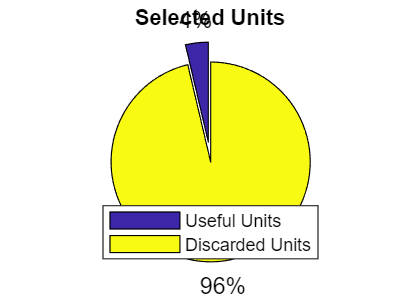

pie([n_slim_pickings/sum(strcmp(glodb.AP_quality, 'good'))*100 100-n_slim_pickings/sum(strcmp(glodb.AP_quality, 'good'))*100], [1 1])
legend({'Useful Units', 'Discarded Units'}, 'Location', 'SouthWest')
title('Selected Units')

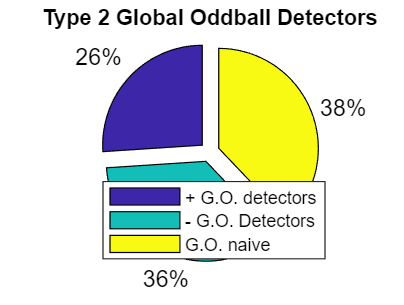

global_units_type_2 = find(glodb.GLO_global_oddball_response_type_2_40_500ms_mwu(slim_pickings) < 0.05 | ...
    glodb.GLO_global_oddball_response_type_2_40_90ms_mwu(slim_pickings) < 0.05 | ...
    glodb.GLO_global_oddball_response_type_2_100_500ms_mwu(slim_pickings) < 0.05);
n_global_units_type_2 = numel(global_units_type_2);
pct_global_units_type_2 = numel(global_units_type_2) / n_slim_pickings * 100;
global_units_type_2_pos = find((glodb.GLO_global_oddball_response_type_2_40_500ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_global_oddball_response_type_2_40_500ms_mean_diff(slim_pickings) > 0) | ...
    (glodb.GLO_global_oddball_response_type_2_40_90ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_global_oddball_response_type_2_40_90ms_mean_diff(slim_pickings) > 0) | ...
    (glodb.GLO_global_oddball_response_type_2_100_500ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_global_oddball_response_type_2_100_500ms_mean_diff(slim_pickings) > 0));
pct_global_units_type_2_pos = numel(global_units_type_2_pos) / n_slim_pickings * 100;
global_units_type_2_neg = find((glodb.GLO_global_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_global_oddball_response_type_2_40_500ms_mean_diff(slim_pickings) < 0) | ...
    (glodb.GLO_global_oddball_response_type_2_40_90ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_global_oddball_response_type_2_40_90ms_mean_diff(slim_pickings) < 0) | ...
    (glodb.GLO_global_oddball_response_type_2_100_500ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_global_oddball_response_type_2_100_500ms_mean_diff(slim_pickings) < 0));
pct_global_units_type_2_neg = numel(global_units_type_2_neg) / n_slim_pickings * 100;

pie([pct_global_units_type_2_pos pct_global_units_type_2_neg 100-pct_global_units_type_2], [1,1,1])
legend({'+ G.O. detectors', '- G.O. Detectors', 'G.O. naive'}, 'Location', 'SouthWest')
axis square
title('Type 2 Global Oddball Detectors')

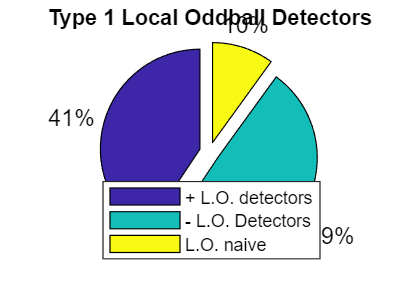

local_units_type_1 = find(glodb.GLO_local_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 | ...
    glodb.GLO_local_oddball_response_type_1_40_90ms_mwu(slim_pickings) < 0.05 | ...
    glodb.GLO_local_oddball_response_type_1_100_500ms_mwu(slim_pickings) < 0.05);
n_local_units_type_1 = numel(local_units_type_1);
pct_local_units_type_1 = numel(local_units_type_1) / n_slim_pickings * 100;
local_units_type_1_pos = find((glodb.GLO_local_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_local_oddball_response_type_1_40_90ms_mean_diff(slim_pickings) > 0) | ...
    (glodb.GLO_local_oddball_response_type_1_40_90ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_local_oddball_response_type_1_40_90ms_mean_diff(slim_pickings) > 0) | ...
    (glodb.GLO_local_oddball_response_type_1_100_500ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_local_oddball_response_type_1_40_90ms_mean_diff(slim_pickings) > 0));
n_local_units_type_1_pos = numel(local_units_type_1_pos);
pct_local_units_type_1_pos = numel(local_units_type_1_pos) / n_slim_pickings * 100;
local_units_type_1_neg = find((glodb.GLO_local_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_local_oddball_response_type_1_40_90ms_mean_diff(slim_pickings) < 0) | ...
    (glodb.GLO_local_oddball_response_type_1_40_90ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_local_oddball_response_type_1_40_90ms_mean_diff(slim_pickings) < 0) | ...
    (glodb.GLO_local_oddball_response_type_1_100_500ms_mwu(slim_pickings) < 0.05 & ...
    glodb.GLO_local_oddball_response_type_1_40_90ms_mean_diff(slim_pickings) < 0));
n_local_units_type_1_neg = numel(local_units_type_1_neg);
pct_local_units_type_1_neg = numel(local_units_type_1_neg) / n_slim_pickings * 100;

pie([pct_local_units_type_1_pos pct_local_units_type_1_neg 100-pct_local_units_type_1], [1,1,1])
legend({'+ L.O. detectors', '- L.O. Detectors', 'L.O. naive'}, 'Location', 'SouthWest')
axis square
title('Type 1 Local Oddball Detectors')

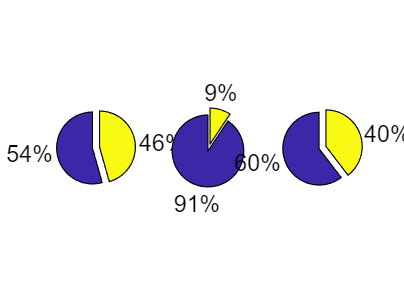

local_global_detectors_2_1 = find((glodb.GLO_global_oddball_response_type_2_40_500ms_mwu(slim_pickings) < 0.05 | ...
    glodb.GLO_global_oddball_response_type_2_40_90ms_mwu(slim_pickings) < 0.05 | ...
    glodb.GLO_global_oddball_response_type_2_100_500ms_mwu(slim_pickings) < 0.05) & ...
    (glodb.GLO_local_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 | ...
    glodb.GLO_local_oddball_response_type_1_40_90ms_mwu(slim_pickings) < 0.05 | ...
    glodb.GLO_local_oddball_response_type_1_100_500ms_mwu(slim_pickings) < 0.05));
n_local_global_detectors_2_1 = numel(local_global_detectors_2_1);
pct_local_global_detectors_2_1 = numel(local_global_detectors_2_1) / n_slim_pickings * 100;
pct_global_local_global_detectors_2_1 = numel(local_global_detectors_2_1) / n_global_units_type_2 * 100;
pct_local_local_global_detectors_2_1 = numel(local_global_detectors_2_1) / n_local_units_type_1 * 100;

subplot(1,3,1); pie([pct_local_global_detectors_2_1 100-pct_local_global_detectors_2_1], [1,1]);
subplot(1,3,2); pie([pct_global_local_global_detectors_2_1 100-pct_global_local_global_detectors_2_1], [1,1])
subplot(1,3,3); pie([pct_local_local_global_detectors_2_1 100-pct_local_local_global_detectors_2_1], [1,1])

opto_activated = [];

for i = 1:numel(slim_pickings)
    if (glodb.OPTO_40hz_1point35_wsr(slim_pickings(i)) < 0.05 & ...
            max(abs(glodb.OPTO_40hz_1point35_mean{slim_pickings(i)})) > 10) | ...
            (glodb.OPTO_5hz_1point35_wsr(slim_pickings(i)) < 0.05 & ...
            max(abs(glodb.OPTO_5hz_1point35_mean{slim_pickings(i)})) > 10)

        opto_activated = [opto_activated i];

    end
end
n_opto_activated = numel(opto_activated);

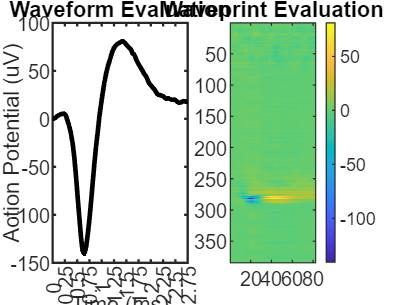

unit = slim_pickings(53);

figure; subplot(1,2,1)
plot(0:81, glodb.AP_waveform{unit}, 'color', 'k', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [0 81], 'xtick', 0:7.3636:81,'xticklabel',0:.25:2.75)
xlabel('Time (ms)')
ylabel('Action Potential (uV)')
title('Waveform Evaluation') 
subplot(1,2,2); imagesc(glodb.AP_waveprint{unit}'); colorbar; title('Waveprint Evaluation')

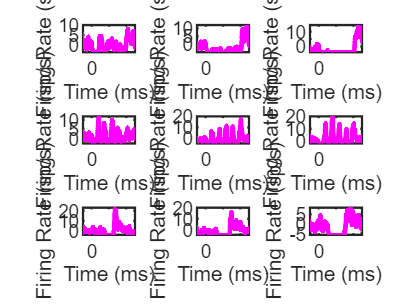

 unit = slim_pickings(opto_activated(11));
 
 figure; 
 for i = 1:9
     subplot(3,3,i); hold on;
     if i == 1; str = 'OPTO_40hz_0point77';
     elseif i == 2; str = 'OPTO_40hz_0point97';
     elseif i == 3; str = 'OPTO_40hz_1point35';
     elseif i == 4; str = 'OPTO_5hz_0point77';
     elseif i == 5; str = 'OPTO_5hz_0point97';
     elseif i == 6; str = 'OPTO_5hz_1point35';
     elseif i == 7; str = 'OPTO_cos_0point77';
     elseif i == 8; str = 'OPTO_cos_0point97';
     elseif i == 9; str = 'OPTO_cos_1point35'; 
     end
     plot(-1001:2000, glodb.([str '_mean']){unit}, 'color', 'm', 'linewidth', 2);
     set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-250 1250])
     xlabel('Time (ms)')
     ylabel('Firing Rate (sp/s)')
 end

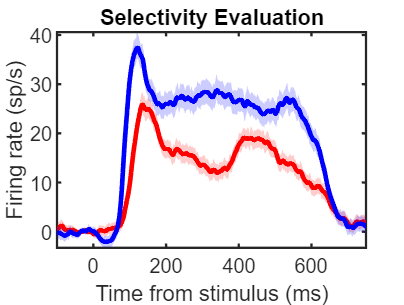

unit = slim_pickings(17);

figure; hold on
plot_ci(glodb.GLO_rndctl_global_stimulus_mean{unit}-(1.96.*(glodb.GLO_rndctl_global_stimulus_sd{unit}./sqrt(glodb.GLO_rndctl_global_stimulus_n(unit)))), ...
    glodb.GLO_rndctl_global_stimulus_mean{unit}+(1.96.*(glodb.GLO_rndctl_global_stimulus_sd{unit}./sqrt(glodb.GLO_rndctl_global_stimulus_n(unit)))), -501:1000, 'r', .2)
plot(-501:1000, smooth(glodb.GLO_rndctl_global_stimulus_mean{unit}, 10), 'color', 'r', 'linewidth', 2);
plot_ci(glodb.GLO_rndctl_local_stimulus_mean{unit}-(1.96.*(glodb.GLO_rndctl_local_stimulus_sd{unit}./sqrt(glodb.GLO_rndctl_local_stimulus_n(unit)))), ...
    glodb.GLO_rndctl_local_stimulus_mean{unit}+(1.96.*(glodb.GLO_rndctl_local_stimulus_sd{unit}./sqrt(glodb.GLO_rndctl_local_stimulus_n(unit)))), -501:1000, 'b', .2)
plot(-501:1000, smooth(glodb.GLO_rndctl_local_stimulus_mean{unit}, 10), 'color', 'b', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
xlabel('Time from stimulus (ms)')
ylabel('Firing rate (sp/s)')
title('Selectivity Evaluation')

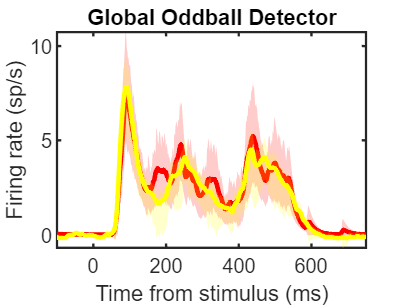

%unit = slim_pickings(global_units_type_2(96));
unit = slim_pickings(91);

figure; hold on
plot_ci(glodb.GLO_gloexp_global_oddball_mean{unit}-(1.96.*(glodb.GLO_gloexp_global_oddball_sd{unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(unit)))), ...
    glodb.GLO_gloexp_global_oddball_mean{unit}+(1.96.*(glodb.GLO_gloexp_global_oddball_sd{unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(unit)))), -501:1000, 'r', .2)
go = plot(-501:1000, smooth(glodb.GLO_gloexp_global_oddball_mean{unit}, 10), 'color', 'r', 'linewidth', 2);
plot_ci(glodb.GLO_gloexp_pres3_mean{unit}-(1.96.*(glodb.GLO_gloexp_global_oddball_sd{unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(unit)))), ...
    glodb.GLO_gloexp_pres3_mean{unit}+(1.96.*(glodb.GLO_gloexp_pres3_sd{unit}./sqrt(glodb.GLO_gloexp_pres3_n(unit)))), -501:1000, 'y', .2)
g3 = plot(-501:1000, smooth(glodb.GLO_gloexp_pres3_mean{unit}, 10), 'color', 'y', 'linewidth', 2);
%plot_ci(glodb.GLO_seqctl_matched_global_stimulus_mean{unit}-(1.96.*(glodb.GLO_seqctl_matched_global_stimulus_sd{unit}./sqrt(glodb.GLO_seqctl_matched_global_stimulus_n(unit)))), ...
%    glodb.GLO_seqctl_matched_global_stimulus_mean{unit}+(1.96.*(glodb.GLO_seqctl_matched_global_stimulus_sd{unit}./sqrt(glodb.GLO_seqctl_matched_global_stimulus_n(unit)))), -501:1000, 'k', .2)
%cc = plot(-501:1000, smooth(glodb.GLO_seqctl_matched_global_stimulus_mean{unit}, 10), 'color', 'k', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
xlabel('Time from stimulus (ms)')
ylabel('Firing rate (sp/s)')
title('Global Oddball Detector')

%legend([go, g3, cc], {'Global Oddball', 'P3', 'Control Comp.'}, 'Location', 'NorthWest')

%unit = slim_pickings(global_units_type_2(96));
unit = slim_pickings(82);

figure; hold on
plot_ci((glodb.GLO_gloexp_global_oddball_mean{unit}-glodb.GLO_gloexp_pres3_mean{unit})-(1.96.*(glodb.GLO_gloexp_global_oddball_sd{unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(unit)))), ...
    (glodb.GLO_gloexp_global_oddball_mean{unit}-glodb.GLO_gloexp_pres3_mean{unit})+(1.96.*(glodb.GLO_gloexp_global_oddball_sd{unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(unit)))), -501:1000, 'm', .2)
plot_ci((glodb.GLO_gloexp_local_oddball_mean{unit}-smooth(glodb.GLO_rndctl_local_stimulus_mean{unit})-(1.96.*(glodb.GLO_gloexp_global_oddball_sd{unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(unit)))), ...
    (glodb.GLO_gloexp_local_oddball_mean{unit}-smooth(glodb.GLO_rndctl_local_stimulus_mean{unit})+(1.96.*(glodb.GLO_gloexp_global_oddball_sd{unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(unit)))), -501:1000, 'c', .2)
go = plot(-501:1000, smooth(glodb.GLO_gloexp_global_oddball_mean{unit}, 10) - smooth(glodb.GLO_gloexp_pres3_mean{unit}, 10), 'color', 'm', 'linewidth', 2);
go = plot(-501:1000, smooth(glodb.GLO_gloexp_local_oddball_mean{unit}, 10) - smooth(glodb.GLO_rndctl_local_stimulus_mean{unit}, 10), 'color', 'c', 'linewidth', 2);
go = plot(-501:1000, zeros(1502,1), 'color', 'k', 'linewidth', 2, 'linestyle', ':');
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
xlabel('Time from stimulus (ms)')
ylabel('Firing rate (sp/s)')
title('Global Oddball Detector')
%legend([go, g3, cc], {'Global Oddball', 'P3', 'Control Comp.'}, 'Location', 'NorthWest')

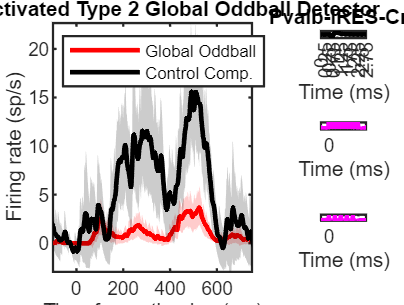

temp_combo_global = ismember(global_units_type_2, opto_activated);
temp_combo_global = global_units_type_2(temp_combo_global);
n_temp_combo = numel(temp_combo_global);
unit = slim_pickings(temp_combo_global(33));

figure; subplot(3,3,[1 2 4 5 7 8]); hold on;
plot_ci(glodb.GLO_gloexp_global_oddball_mean{unit}-(1.96.*(glodb.GLO_gloexp_global_oddball_sd{unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(unit)))), ...
    glodb.GLO_gloexp_global_oddball_mean{unit}+(1.96.*(glodb.GLO_gloexp_global_oddball_sd{unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(unit)))), -501:1000, 'r', .2)
go = plot(-501:1000, smooth(glodb.GLO_gloexp_global_oddball_mean{unit}, 10), 'color', 'r', 'linewidth', 2);
plot_ci(glodb.GLO_seqctl_matched_global_stimulus_mean{unit}-(1.96.*(glodb.GLO_seqctl_matched_global_stimulus_sd{unit}./sqrt(glodb.GLO_seqctl_matched_global_stimulus_n(unit)))), ...
    glodb.GLO_seqctl_matched_global_stimulus_mean{unit}+(1.96.*(glodb.GLO_seqctl_matched_global_stimulus_sd{unit}./sqrt(glodb.GLO_seqctl_matched_global_stimulus_n(unit)))), -501:1000, 'k', .2)
cc = plot(-501:1000, smooth(glodb.GLO_seqctl_matched_global_stimulus_mean{unit}, 10), 'color', 'k', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
xlabel('Time from stimulus (ms)')
ylabel('Firing rate (sp/s)')
title('Opto-activated Type 2 Global Oddball Detector')
legend([go, cc], {'Global Oddball', 'Control Comp.'}, 'Location', 'NorthWest')

subplot(3,3,3)
plot(0:81, glodb.AP_waveform{unit}, 'color', 'k', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [0 81], 'xtick', 0:7.3636:81,'xticklabel',0:.25:2.75)
xlabel('Time (ms)')
ylabel('Action Potential (uV)')
title(glodb.INFO_genotype{unit}(1:14))

subplot(3,3,6);
plot(-1001:2000, glodb.OPTO_40hz_1point35_mean{unit}, 'color', 'm', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-250 1250])
xlabel('Time (ms)')
ylabel('Firing Rate (sp/s)')

subplot(3,3,9);
plot(-1001:2000, glodb.OPTO_5hz_1point35_mean{unit}, 'color', 'm', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-250 1250])
xlabel('Time (ms)')
ylabel('Firing Rate (sp/s)')

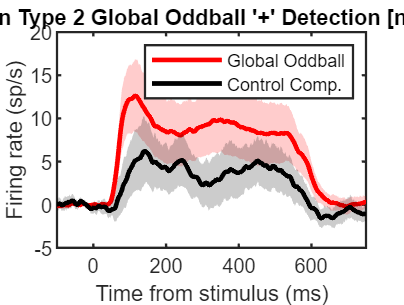

figure; hold on
for i = 1 : numel(global_units_type_2_pos); dat(:,i) = glodb.GLO_gloexp_global_oddball_mean{slim_pickings(global_units_type_2_pos(i))}; end
plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'r', .2)
go = plot(-501:1000, smooth(mean(dat,2),10), 'color', 'r', 'linewidth', 2); clear dat;
for i = 1 : numel(global_units_type_2_pos); dat(:,i) = glodb.GLO_seqctl_matched_global_stimulus_mean{slim_pickings(global_units_type_2_pos(i))}; end 
plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'k', .2)
cc = plot(-501:1000, smooth(mean(dat,2),10), 'color', 'k', 'linewidth', 2); clear dat;
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
xlabel('Time from stimulus (ms)')
ylabel('Firing rate (sp/s)')
title(['Population Type 2 Global Oddball ''+'' Detection [n=' num2str(numel(global_units_type_2_pos)) ', ' num2str(numel(global_units_type_2_pos)/n_slim_pickings*100) '%]'])
legend([go, cc], {'Global Oddball', 'Control Comp.'}, 'Location', 'NorthEast')

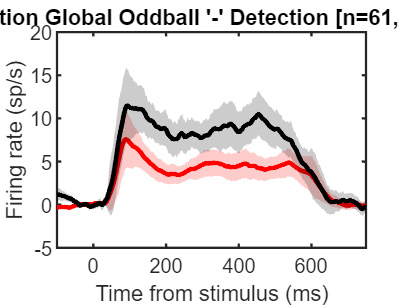

figure; hold on
for i = 1 : numel(global_units_type_2_neg); dat(:,i) = glodb.GLO_gloexp_global_oddball_mean{slim_pickings(global_units_type_2_neg(i))}; end
plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'r', .2)
plot(-501:1000, smooth(mean(dat,2),10), 'color', 'r', 'linewidth', 2); clear dat;
for i = 1 : numel(global_units_type_2_neg); dat(:,i) = glodb.GLO_seqctl_matched_global_stimulus_mean{slim_pickings(global_units_type_2_neg(i))}; end 
plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'k', .2)
plot(-501:1000, smooth(mean(dat, 2),10), 'color', 'k', 'linewidth', 2); clear dat;
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
xlabel('Time from stimulus (ms)')
ylabel('Firing rate (sp/s)')
title(['Population Global Oddball ''-'' Detection [n=' num2str(numel(global_units_type_2_neg)) ', ' num2str(numel(global_units_type_2_neg)/n_slim_pickings*100) '%]'])

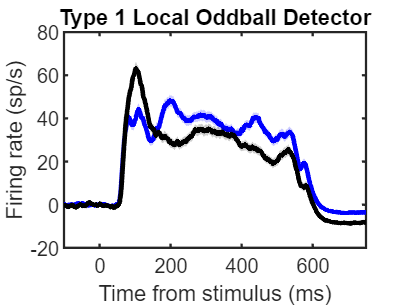

local_unit = slim_pickings(local_units_type_1(87));

figure; hold on
plot_ci(glodb.GLO_gloexp_local_oddball_mean{local_unit}-(1.96.*(glodb.GLO_gloexp_local_oddball_sd{local_unit}./sqrt(glodb.GLO_gloexp_local_oddball_n(local_unit)))), ...
    glodb.GLO_gloexp_local_oddball_mean{local_unit}+(1.96.*(glodb.GLO_gloexp_local_oddball_sd{local_unit}./sqrt(glodb.GLO_gloexp_local_oddball_n(local_unit)))), -501:1000, 'b', .2)
plot(-501:1000, glodb.GLO_gloexp_local_oddball_mean{local_unit}, 'color', 'b', 'linewidth', 2);
plot_ci(glodb.GLO_rndctl_local_stimulus_mean{local_unit}-(1.96.*(glodb.GLO_rndctl_local_stimulus_sd{local_unit}./sqrt(glodb.GLO_rndctl_local_stimulus_n(local_unit)))), ...
    glodb.GLO_rndctl_local_stimulus_mean{local_unit}+(1.96.*(glodb.GLO_rndctl_local_stimulus_sd{local_unit}./sqrt(glodb.GLO_rndctl_local_stimulus_n(local_unit)))), -501:1000, 'k', .2)
plot(-501:1000, glodb.GLO_rndctl_local_stimulus_mean{local_unit}, 'color', 'k', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
xlabel('Time from stimulus (ms)')
ylabel('Firing rate (sp/s)')
title('Type 1 Local Oddball Detector')

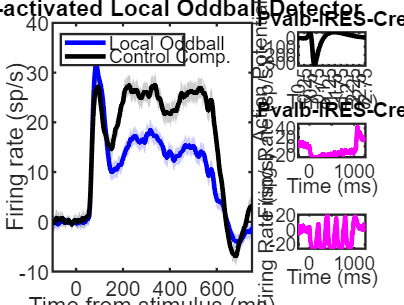

temp_combo_local = ismember(local_units_type_1, opto_activated);
temp_combo_local = local_units_type_1(temp_combo_local);
n_temp_combo = numel(temp_combo_local);
local_unit = slim_pickings(temp_combo_local(96));

figure; subplot(2,3,[1 2 4 5]); hold on;
plot_ci(glodb.GLO_gloexp_local_oddball_mean{local_unit}-(1.96.*(glodb.GLO_gloexp_local_oddball_sd{local_unit}./sqrt(glodb.GLO_gloexp_local_oddball_n(local_unit)))), ...
    glodb.GLO_gloexp_local_oddball_mean{local_unit}+(1.96.*(glodb.GLO_gloexp_local_oddball_sd{local_unit}./sqrt(glodb.GLO_gloexp_local_oddball_n(local_unit)))), -501:1000, 'b', .2)
go = plot(-501:1000, smooth(glodb.GLO_gloexp_local_oddball_mean{local_unit}, 10), 'color', 'b', 'linewidth', 2);
plot_ci(glodb.GLO_rndctl_local_stimulus_mean{local_unit}-(1.96.*(glodb.GLO_rndctl_local_stimulus_sd{local_unit}./sqrt(glodb.GLO_rndctl_local_stimulus_n(local_unit)))), ...
    glodb.GLO_rndctl_local_stimulus_mean{local_unit}+(1.96.*(glodb.GLO_rndctl_local_stimulus_sd{local_unit}./sqrt(glodb.GLO_rndctl_local_stimulus_n(local_unit)))), -501:1000, 'k', .2)
cc = plot(-501:1000, smooth(glodb.GLO_rndctl_local_stimulus_mean{local_unit}, 10), 'color', 'k', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
xlabel('Time from stimulus (ms)')
ylabel('Firing rate (sp/s)')
title('Opto-activated Local Oddball Detector')
legend([go, cc], {'Local Oddball', 'Control Comp.'}, 'Location', 'NorthWest')

subplot(3,3,3)
plot(0:81, glodb.AP_waveform{local_unit}, 'color', 'k', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [0 81], 'xtick', 0:7.3636:81,'xticklabel',0:.25:2.75)
xlabel('Time (ms)')
ylabel('Action Potential (uV)')
title(glodb.INFO_genotype{local_unit}(1:14))

subplot(3,3,6);
plot(-1001:2000, glodb.OPTO_40hz_1point35_mean{local_unit}, 'color', 'm', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-250 1250])
xlabel('Time (ms)')
ylabel('Firing Rate (sp/s)')
title(glodb.INFO_genotype{local_unit}(1:14))

subplot(3,3,9);
plot(-1001:2000, glodb.OPTO_5hz_1point35_mean{local_unit}, 'color', 'm', 'linewidth', 2);
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-250 1250])
xlabel('Time (ms)')
ylabel('Firing Rate (sp/s)')

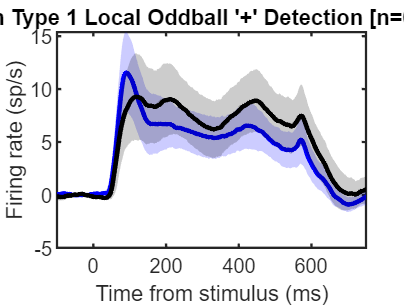

figure; hold on
for i = 1 : numel(local_units_type_1_pos); dat(:,i) = glodb.GLO_gloexp_local_oddball_mean{slim_pickings(local_units_type_1_pos(i))}; end
plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'b', .2)
h_global = plot(-501:1000, smooth(mean(dat,2),10), 'color', 'b', 'linewidth', 2); clear dat;
for i = 1 : numel(local_units_type_1_pos); dat(:,i) = glodb.GLO_rndctl_local_stimulus_mean{slim_pickings(local_units_type_1_pos(i))}; end
plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'k', .2)
h_pres3 = plot(-501:1000, smooth(mean(dat, 2),10), 'color', 'k', 'linewidth', 2); clear dat;
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
xlabel('Time from stimulus (ms)')
ylabel('Firing rate (sp/s)')
title(['Population Type 1 Local Oddball ''+'' Detection [n=' num2str(numel(local_units_type_1_pos)) ', ' num2str(numel(local_units_type_1_pos)/n_slim_pickings*100) '%]'])

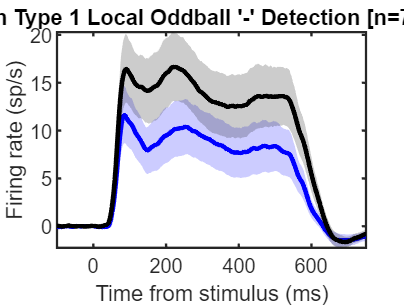

figure; hold on
for i = 1 : numel(local_units_type_1_neg); dat(:,i) = glodb.GLO_gloexp_local_oddball_mean{slim_pickings(local_units_type_1_neg(i))}; end
plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'b', .2)
h_global = plot(-501:1000, smooth(mean(dat,2),10), 'color', 'b', 'linewidth', 2); clear dat;
for i = 1 : numel(local_units_type_1_neg); dat(:,i) = glodb.GLO_rndctl_local_stimulus_mean{slim_pickings(local_units_type_1_neg(i))}; end
plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'k', .2)
h_pres3 = plot(-501:1000, smooth(mean(dat, 2),10), 'color', 'k', 'linewidth', 2); clear dat;
set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
xlabel('Time from stimulus (ms)')
ylabel('Firing rate (sp/s)')
title(['Population Type 1 Local Oddball ''-'' Detection [n=' num2str(numel(local_units_type_1_neg)) ', ' num2str(numel(local_units_type_1_neg)/n_slim_pickings*100) '%]'])

% global_units_type_1 = find(glodb.GLO_global_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_global_oddball_response_type_1_40_90ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_global_oddball_response_type_1_100_500ms_mwu(slim_pickings) < 0.05);
% n_global_units_type_1 = numel(global_units_type_1);
% pct_global_units_type_1 = numel(global_units_type_1) / n_slim_pickings * 100;
% global_units_type_1_pos = find((glodb.GLO_global_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_global_oddball_response_type_1_40_500ms_mean_diff(slim_pickings) > 0) | ...
%     (glodb.GLO_global_oddball_response_type_1_40_90ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_global_oddball_response_type_1_40_90ms_mean_diff(slim_pickings) > 0) | ...
%     (glodb.GLO_global_oddball_response_type_1_100_500ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_global_oddball_response_type_1_100_500ms_mean_diff(slim_pickings) > 0));
% pct_global_units_type_1_pos = numel(global_units_type_1_pos) / n_slim_pickings * 100;
% global_units_type_1_neg = find((glodb.GLO_global_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_global_oddball_response_type_1_40_500ms_mean_diff(slim_pickings) < 0) | ...
%     (glodb.GLO_global_oddball_response_type_1_40_90ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_global_oddball_response_type_1_40_90ms_mean_diff(slim_pickings) < 0) | ...
%     (glodb.GLO_global_oddball_response_type_1_100_500ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_global_oddball_response_type_1_100_500ms_mean_diff(slim_pickings) < 0));
% pct_global_units_type_1_neg = numel(global_units_type_1_neg) / n_slim_pickings * 100;
% 
% pie([pct_global_units_type_1_pos pct_global_units_type_1_neg 100-pct_global_units_type_1], [1,1,1])
% legend({'+ G.O. detectors', '- G.O. Detectors', 'G.O. naive'}, 'Location', 'SouthWest')
% axis square
% title('Type 1 Global Oddball Detectors')

% local_units_type_2 = find(glodb.GLO_local_oddball_response_type_2_40_500ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_local_oddball_response_type_2_40_90ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_local_oddball_response_type_2_100_500ms_mwu(slim_pickings) < 0.05);
% n_local_units_type_2 = numel(local_units_type_2);
% pct_local_units_type_2 = numel(local_units_type_2) / n_slim_pickings * 100;
% local_units_type_2_pos = find((glodb.GLO_local_oddball_response_type_2_40_500ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_local_oddball_response_type_2_40_90ms_mean_diff(slim_pickings) > 0) | ...
%     (glodb.GLO_local_oddball_response_type_2_40_90ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_local_oddball_response_type_2_40_90ms_mean_diff(slim_pickings) > 0) | ...
%     (glodb.GLO_local_oddball_response_type_2_100_500ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_local_oddball_response_type_2_40_90ms_mean_diff(slim_pickings) > 0));
% n_local_units_type_2_pos = numel(local_units_type_2_pos);
% pct_local_units_type_2_pos = numel(local_units_type_2_pos) / n_slim_pickings * 100;
% local_units_type_2_neg = find((glodb.GLO_local_oddball_response_type_2_40_500ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_local_oddball_response_type_2_40_90ms_mean_diff(slim_pickings) < 0) | ...
%     (glodb.GLO_local_oddball_response_type_2_40_90ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_local_oddball_response_type_2_40_90ms_mean_diff(slim_pickings) < 0) | ...
%     (glodb.GLO_local_oddball_response_type_2_100_500ms_mwu(slim_pickings) < 0.05 & ...
%     glodb.GLO_local_oddball_response_type_2_40_90ms_mean_diff(slim_pickings) < 0));
% n_local_units_type_2_neg = numel(local_units_type_2_neg);
% pct_local_units_type_2_neg = numel(local_units_type_2_neg) / n_slim_pickings * 100;
% 
% pie([pct_local_units_type_2_pos pct_local_units_type_2_neg 100-pct_local_units_type_2], [1,1,1])
% legend({'+ L.O. detectors', '- L.O. Detectors', 'L.O. naive'}, 'Location', 'SouthEast')
% axis square
% title('Type 2 Local Oddball Detectors')

% local_global_detectors_1_1 = find((glodb.GLO_global_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_global_oddball_response_type_1_40_90ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_global_oddball_response_type_1_100_500ms_mwu(slim_pickings) < 0.05) & ...
%     (glodb.GLO_local_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_local_oddball_response_type_1_40_90ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_local_oddball_response_type_1_100_500ms_mwu(slim_pickings) < 0.05));
% n_local_global_detectors_1_1 = numel(local_global_detectors_1_1);
% pct_local_global_detectors_1_1 = numel(local_global_detectors_1_1) / n_slim_pickings * 100;
% pct_global_local_global_detectors_1_1 = numel(local_global_detectors_1_1) / n_global_units_type_1 * 100;
% pct_local_local_global_detectors_1_1 = numel(local_global_detectors_1_1) / n_local_units_type_1 * 100;
% 
% subplot(1,3,1); pie([pct_local_global_detectors_1_1 100-pct_local_global_detectors_1_1], [1,1]);
% subplot(1,3,2); pie([pct_global_local_global_detectors_1_1 100-pct_global_local_global_detectors_1_1], [1,1])
% subplot(1,3,3); pie([pct_local_local_global_detectors_1_1 100-pct_local_local_global_detectors_1_1], [1,1])

% local_global_detectors_1_2 = find((glodb.GLO_global_oddball_response_type_1_40_500ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_global_oddball_response_type_1_40_90ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_global_oddball_response_type_1_100_500ms_mwu(slim_pickings) < 0.05) & ...
%     (glodb.GLO_local_oddball_response_type_2_40_500ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_local_oddball_response_type_2_40_90ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_local_oddball_response_type_2_100_500ms_mwu(slim_pickings) < 0.05));
% n_local_global_detectors_1_2 = numel(local_global_detectors_1_2);
% pct_local_global_detectors_1_2 = numel(local_global_detectors_1_2) / n_slim_pickings * 100;
% pct_global_local_global_detectors_1_2 = numel(local_global_detectors_1_2) / n_global_units_type_1 * 100;
% pct_local_local_global_detectors_1_2 = numel(local_global_detectors_1_2) / n_local_units_type_2 * 100;
% 
% subplot(1,3,1); pie([pct_local_global_detectors_1_2 100-pct_local_global_detectors_1_2], [1,1]);
% subplot(1,3,2); pie([pct_global_local_global_detectors_1_2 100-pct_global_local_global_detectors_1_2], [1,1])
% subplot(1,3,3); pie([pct_local_local_global_detectors_1_2 100-pct_local_local_global_detectors_1_2], [1,1])


% local_global_detectors_2_2 = find((glodb.GLO_global_oddball_response_type_2_40_500ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_global_oddball_response_type_2_40_90ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_global_oddball_response_type_2_100_500ms_mwu(slim_pickings) < 0.05) & ...
%     (glodb.GLO_local_oddball_response_type_2_40_500ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_local_oddball_response_type_2_40_90ms_mwu(slim_pickings) < 0.05 | ...
%     glodb.GLO_local_oddball_response_type_2_100_500ms_mwu(slim_pickings) < 0.05));
% n_local_global_detectors_2_2 = numel(local_global_detectors_2_2);
% pct_local_global_detectors_2_2 = numel(local_global_detectors_2_2) / n_slim_pickings * 100;
% pct_global_local_global_detectors_2_2 = numel(local_global_detectors_2_2) / n_global_units_type_2 * 100;
% pct_local_local_global_detectors_2_2 = numel(local_global_detectors_2_2) / n_local_units_type_2 * 100;
% 
% subplot(1,3,1); pie([pct_local_global_detectors_2_2 100-pct_local_global_detectors_2_2], [1,1]);
% subplot(1,3,2); pie([pct_global_local_global_detectors_2_2 100-pct_global_local_global_detectors_2_2], [1,1])
% subplot(1,3,3); pie([pct_local_local_global_detectors_2_2 100-pct_local_local_global_detectors_2_2], [1,1])

% local_unit = slim_pickings(local_units_type_2(77));
% 
% figure; hold on
% plot_ci(glodb.GLO_gloexp_local_oddball_mean{local_unit}-(1.96.*(glodb.GLO_gloexp_local_oddball_sd{local_unit}./sqrt(glodb.GLO_gloexp_local_oddball_n(local_unit)))), ...
%     glodb.GLO_gloexp_local_oddball_mean{local_unit}+(1.96.*(glodb.GLO_gloexp_local_oddball_sd{local_unit}./sqrt(glodb.GLO_gloexp_local_oddball_n(local_unit)))), -501:1000, 'b', .2)
% plot(-501:1000, glodb.GLO_gloexp_local_oddball_mean{local_unit}, 'color', 'b', 'linewidth', 2);
% plot_ci(glodb.GLO_rndctl_matched_local_stimulus_mean{local_unit}-(1.96.*(glodb.GLO_rndctl_matched_local_stimulus_sd{local_unit}./sqrt(glodb.GLO_rndctl_matched_local_stimulus_n(local_unit)))), ...
%     glodb.GLO_rndctl_matched_local_stimulus_mean{local_unit}+(1.96.*(glodb.GLO_rndctl_matched_local_stimulus_sd{local_unit}./sqrt(glodb.GLO_rndctl_matched_local_stimulus_n(local_unit)))), -501:1000, 'k', .2)
% plot(-501:1000, glodb.GLO_rndctl_matched_local_stimulus_mean{local_unit}, 'color', 'k', 'linewidth', 2);
% set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
% xlabel('Time from stimulus (ms)')
% ylabel('Firing rate (sp/s)')
% annotation(gcf, 'textbox', 'String',['Power: ' num2str(.01 * floor(glodb.GLO_local_oddball_response_type_2_40_500ms_power(global_unit)*100)) ' ' ...
%     'n_{0.8}: ' num2str(glodb.GLO_local_oddball_response_type_2_40_500ms_nout_point8(global_unit))],'FitBoxToText','on','Position', [.725 .9 .2 0] , 'LineStyle', 'none', 'FontWeight', 'bold');
% title('Type 2 Local Oddball Detector')

% global_unit = slim_pickings(global_units_type_1(32));
% 
% figure; hold on
% plot_ci(glodb.GLO_gloexp_global_oddball_mean{global_unit}-(1.96.*(glodb.GLO_gloexp_global_oddball_sd{global_unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(global_unit)))), ...
%     glodb.GLO_gloexp_global_oddball_mean{global_unit}+(1.96.*(glodb.GLO_gloexp_global_oddball_sd{global_unit}./sqrt(glodb.GLO_gloexp_global_oddball_n(global_unit)))), -501:1000, 'r', .2)
% plot(-501:1000, smooth(glodb.GLO_gloexp_global_oddball_mean{global_unit}, 10), 'color', 'r', 'linewidth', 2);
% plot_ci(glodb.GLO_gloexp_pres3_mean{global_unit}-(1.96.*(glodb.GLO_gloexp_pres3_sd{global_unit}./sqrt(glodb.GLO_gloexp_pres3_n(global_unit)))), ...
%     glodb.GLO_gloexp_pres3_mean{global_unit}+(1.96.*(glodb.GLO_gloexp_pres3_sd{global_unit}./sqrt(glodb.GLO_gloexp_pres3_n(global_unit)))), -501:1000, 'k', .2)
% plot(-501:1000, smooth(glodb.GLO_gloexp_pres3_mean{global_unit}, 10), 'color', 'k', 'linewidth', 2);
% set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
% xlabel('Time from stimulus (ms)')
% ylabel('Firing rate (sp/s)')
% annotation(gcf, 'textbox', 'String',['Power: ' num2str(.01 * floor(glodb.GLO_global_oddball_response_type_1_40_500ms_power(global_unit)*100)) ' ' ...
%     'n_{0.8}: ' num2str(glodb.GLO_global_oddball_response_type_1_40_500ms_nout_point8(global_unit))],'FitBoxToText','on','Position', [.725 .9 .2 0] , 'LineStyle', 'none', 'FontWeight', 'bold');
% title('Type 1 Global Oddball Detector')

% figure; hold on
% for i = 1 : numel(global_units_type_1_pos); dat(:,i) = glodb.GLO_gloexp_global_oddball_mean{slim_pickings(global_units_type_1_pos(i))}; end
% plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'r', .2)
% h_global = plot(-501:1000, smooth(mean(dat,2),10), 'color', 'r', 'linewidth', 2); clear dat;
% for i = 1 : numel(global_units_type_1_pos); dat(:,i) = glodb.GLO_gloexp_pres3_mean{slim_pickings(global_units_type_1_pos(i))}; end
% plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'k', .2)
% h_pres3 = plot(-501:1000, smooth(mean(dat, 2),10), 'color', 'k', 'linewidth', 2); clear dat;
% set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
% xlabel('Time from stimulus (ms)')
% ylabel('Firing rate (sp/s)')
% title(['Population Global Oddball ''+'' Detection [n=' num2str(numel(global_units_type_1_pos)) ', ' num2str(numel(global_units_type_1_pos)/n_slim_pickings*100) '%]'])

% figure; hold on
% for i = 1 : numel(global_units_type_1_neg); dat(:,i) = glodb.GLO_gloexp_global_oddball_mean{slim_pickings(global_units_type_1_neg(i))}; end
% plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'r', .2)
% plot(-501:1000, smooth(mean(dat,2),10), 'color', 'r', 'linewidth', 2); clear dat;
% for i = 1 : numel(global_units_type_1_neg); dat(:,i) = glodb.GLO_gloexp_pres3_mean{slim_pickings(global_units_type_1_neg(i))}; end 
% plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'k', .2)
% plot(-501:1000, smooth(mean(dat, 2),10), 'color', 'k', 'linewidth', 2); clear dat;
% set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
% xlabel('Time from stimulus (ms)')
% ylabel('Firing rate (sp/s)')
% title(['Population Global Oddball ''-'' Detection [n=' num2str(numel(global_units_type_1_neg)) ', ' num2str(numel(global_units_type_1_neg)/n_slim_pickings*100) '%]'])

% figure; hold on
% for i = 1 : numel(local_units_type_2_pos); dat(:,i) = glodb.GLO_gloexp_local_oddball_mean{slim_pickings(local_units_type_2_pos(i))}; end
% plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'b', .2)
% h_global = plot(-501:1000, smooth(mean(dat,2),10), 'color', 'b', 'linewidth', 2); clear dat;
% for i = 1 : numel(local_units_type_2_pos); dat(:,i) = glodb.GLO_rndctl_matched_local_stimulus_mean{slim_pickings(local_units_type_2_pos(i))}; end
% plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'k', .2)
% h_pres3 = plot(-501:1000, smooth(mean(dat, 2),10), 'color', 'k', 'linewidth', 2); clear dat;
% set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
% xlabel('Time from stimulus (ms)')
% ylabel('Firing rate (sp/s)')
% title(['Population Type 2 Local Oddball ''+'' Detection [n=' num2str(numel(local_units_type_1_pos)) ', ' num2str(numel(local_units_type_1_pos)/n_slim_pickings*100) '%]'])

% figure; hold on
% for i = 1 : numel(local_units_type_2_neg); dat(:,i) = glodb.GLO_gloexp_local_oddball_mean{slim_pickings(local_units_type_2_neg(i))}; end
% plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'b', .2)
% h_global = plot(-501:1000, smooth(mean(dat,2),10), 'color', 'b', 'linewidth', 2); clear dat;
% for i = 1 : numel(local_units_type_2_neg); dat(:,i) = glodb.GLO_rndctl_matched_local_stimulus_mean{slim_pickings(local_units_type_2_neg(i))}; end
% plot_ci(mean(dat,2)-(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), mean(dat,2)+(1.96.*(std(dat,[],2)./sqrt(size(dat,2)))), -501:1000, 'k', .2)
% h_pres3 = plot(-501:1000, smooth(mean(dat, 2),10), 'color', 'k', 'linewidth', 2); clear dat;
% set(gca, 'box', 'on', 'linewidth', 1, 'xlim', [-100 750])
% xlabel('Time from stimulus (ms)')
% ylabel('Firing rate (sp/s)')
% title(['Population Type 2 Local Oddball ''-'' Detection [n=' num2str(numel(local_units_type_1_neg)) ', ' num2str(numel(local_units_type_1_neg)/n_slim_pickings*100) '%]'])
